# Cruise Control: Root Locus

Recall the requirement

- Rise time < 5 sec

- Overshoot < 10%

- Steady-state error < 2%

We know the relationship between it and the damping ratio, and natural frequency. We use it to calculate the damping ratio and natural frequency required first

% rise time Tr = 1.8 / wn
wn = 1.8/5;

% damping ratio zeta = sqrt(ln^2(Mp)/(pi^2 + ln^2(Mp))
mp = 0.1;
zeta = sqrt(log(mp)*log(mp)/(pi^2 + log(mp)*log(mp)));

% zeta should be larger than 0.6, and wn is larger than 0.36

## Pure Gain of Root Locus

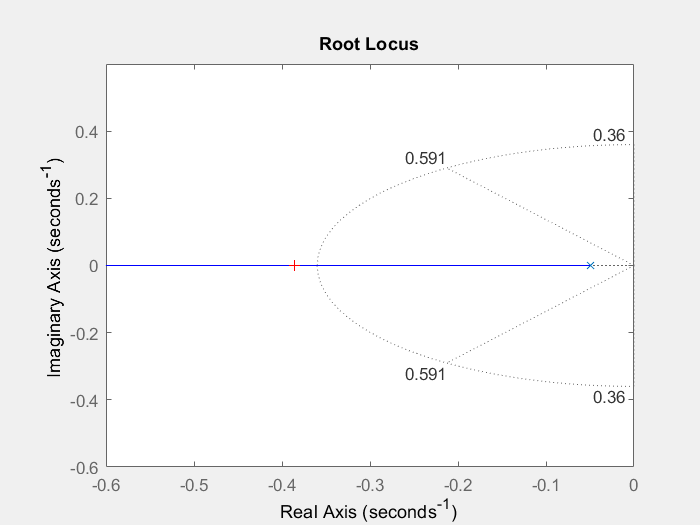

Select a point in the graphics window


selected_point = -0.3858 + 0.0060i

m = 1000;
b = 50;
s = tf('s');
sys_tf = 1/(m*s + b);


rlocus(sys_tf);
axis([-0.6 0 -0.6 0.6]);
sgrid(zeta, wn);
% pick the right location
K = rlocfind(sys_tf);

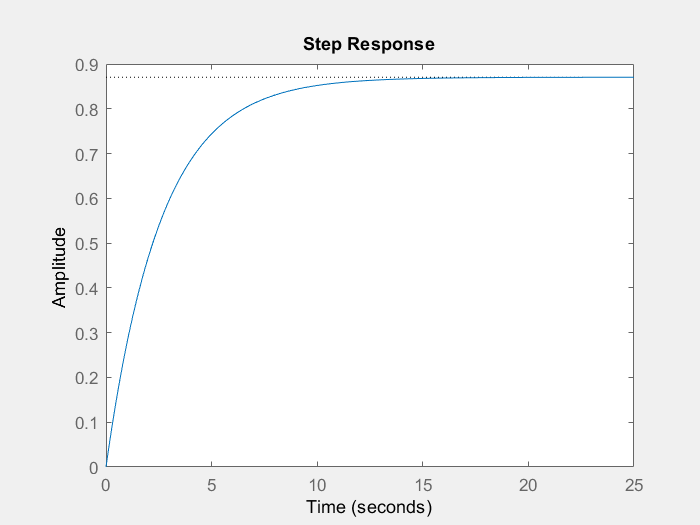

% use this gain K and simulate
sys_cl = feedback(K*sys_tf, 1);
step(sys_cl);

The steady state error is not ok, so we introduce lag compensator

## Lag compensator

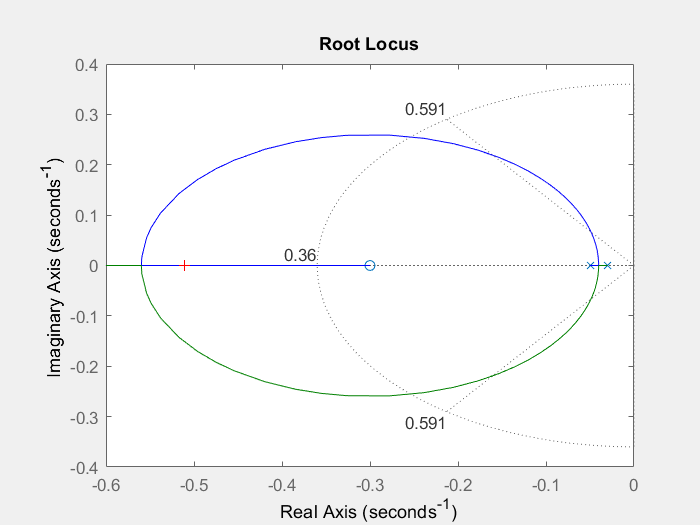

Select a point in the graphics window


selected_point = -0.5108 - 0.0040i

K = 1.0509e+03

zo = 0.3;
po = 0.03;
s = tf('s');
C_lag = (s+zo)/(s+po);

rlocus(C_lag*sys_tf);
axis([-0.6 0 -0.4 0.4]);
sgrid(zeta, wn);
K = rlocfind(C_lag*sys_tf)

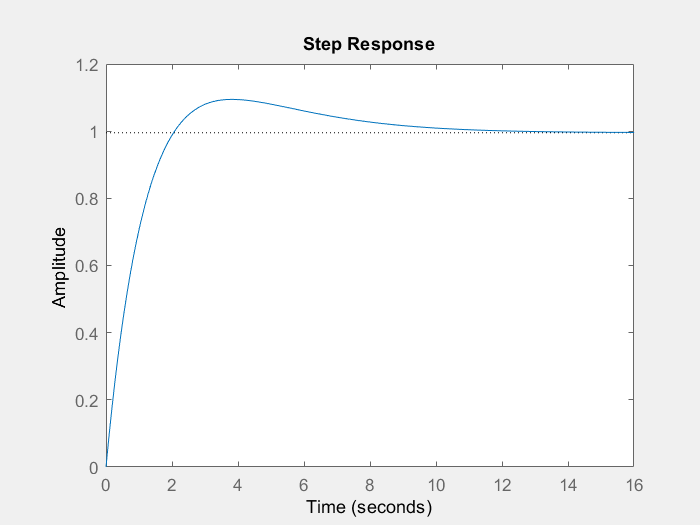

sys_cl = feedback(K*C_lag*sys_tf, 1);
step(sys_cl);